## FFT iterativ

#### Bit reorder

function reordered_signal = custom_bit_reorder(signal)
    N = length(signal);
    bit_reversed_indices = zeros(1, N);
    num_bits = log2(N);                                            % Bit number

    for k = 0:N-1
        reversed_bin = flip(dec2bin(k, num_bits));                 % Convert to Binary and flip
        bit_reversed_indices(k + 1) = bin2dec(reversed_bin) + 1;   % Convert to dec again
    end
    reordered_signal = signal(bit_reversed_indices);               % Reorder signal
end

#### FFT iterative

function [FFT_iterativ_signal_1,FFT_iterativ_signal_2] = FFT_iterativ(h1,h2)
    
    N = length(h1);
    log2N = log2(N);

    h1_reorder = custom_bit_reorder(h1);
    h2_reorder = custom_bit_reorder(h2);
    
    FFT_iterativ_signal_1 = h1_reorder;
    FFT_iterativ_signal_2 = h2_reorder;

    for iteration = 1:log2N                                                                                               % Iteration for each log2
    
        CurrentSignalSize = 2^iteration;                                                                                  % Length of the current signal
        half_CurrentSignalSize = CurrentSignalSize / 2;                                                                   % Find the middel of the current signal
        factor_iteration = exp(-2i * pi * (0:half_CurrentSignalSize-1) / CurrentSignalSize);                              % Calculated factor for the current iteration
    
        for k = 1:CurrentSignalSize:N                                                                                     % Goes from 1 to N in CurrentSignalSize steps/ The amount of iterations I take for the  Original signal length / current Signal lenght
            for l = 0:half_CurrentSignalSize-1                                                                            % Goes from 0 to half of the currentSignalSize because we calculate both halfs at the same time
    
                factor_CurrentPosition_1 = factor_iteration(l+1) * FFT_iterativ_signal_1(k+l+half_CurrentSignalSize);     % Factor for the current signalposition
                CurrentPosition_1 = FFT_iterativ_signal_1(k+l);                                                           % Current signalposition
    
                FFT_iterativ_signal_1(k+l) = CurrentPosition_1 + factor_CurrentPosition_1;                                % Calculation first half
                FFT_iterativ_signal_1(k+l+half_CurrentSignalSize) = CurrentPosition_1 - factor_CurrentPosition_1;         % Calculation last half
    
                factor_CurrentPosition_2 = factor_iteration(l+1) * FFT_iterativ_signal_2(k+l+half_CurrentSignalSize);     % Factor for the current signalposition
                CurrentPosition_2 = FFT_iterativ_signal_2(k+l);                                                           % Current signalposition
    
                FFT_iterativ_signal_2(k+l) = CurrentPosition_2 + factor_CurrentPosition_2;                                % Calculation first half
                FFT_iterativ_signal_2(k+l+half_CurrentSignalSize) = CurrentPosition_2 - factor_CurrentPosition_2;         % Calculation last half
    
            end
        end
    end
end

#### Run FFT

time_FFT_iterativ = tic; % Several times to get a more stable time output
FFT_iterations = 100;
for i = 1:FFT_iterations
[FFT_iterativ_signal_1,FFT_iterativ_signal_2] = FFT_iterativ(h1,h2);
end
time_FFT_iterativ = toc(time_FFT_iterativ)/FFT_iterations

time_FFT_iterativ = 0.1426

#### Shift the end of the signal to the beginning

N=length(h1);
N_half=N/2;

shifted_FFT_iterativ_signal_1 = [FFT_iterativ_signal_1(N_half:end), FFT_iterativ_signal_1(1:N_half-1)];
shifted_FFT_iterativ_signal_2 = [FFT_iterativ_signal_2(N_half:end), FFT_iterativ_signal_2(1:N_half-1)];

shifted_FFT_iterativ_signal_1_magnitude = abs(shifted_FFT_iterativ_signal_1);
shifted_FFT_iterativ_signal_2_magnitude = abs(shifted_FFT_iterativ_signal_2);

% Frequency axis
k=1:N;                                          
f=(k-1)*(1/(N*ts));                   
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));     

#### Plot the DFT, recursive FFT and Matlab calculated FFT

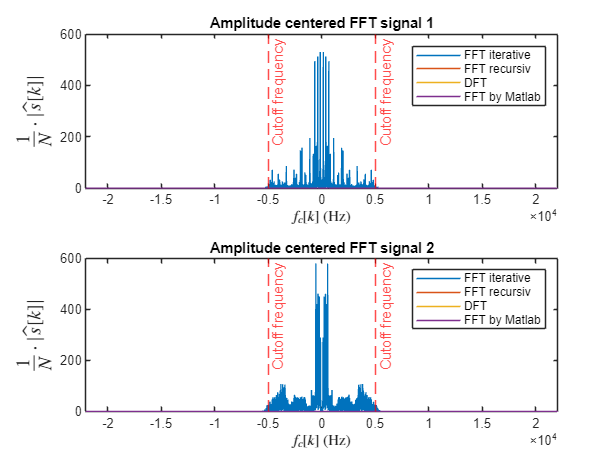

figure;
tiledlayout(2,1)
nexttile
plot(f_c, shifted_FFT_iterativ_signal_1_magnitude);
hold on
plot(f_c, shifted_FFT_recursiv_signal_1_magnitude);
plot(f_c, shifted_DFT_signal_1_magnitude);
plot(f_c, FFT_signal_1_ampl_Matlab)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered FFT signal 1');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT iterative','FFT recursiv','DFT','FFT by Matlab')
xlim([min(f_c) max(f_c)])

nexttile
plot(f_c, shifted_FFT_iterativ_signal_2_magnitude);
hold on
plot(f_c, shifted_FFT_recursiv_signal_2_magnitude);
plot(f_c, shifted_DFT_signal_2_magnitude);
plot(f_c, FFT_signal_2_ampl_Matlab)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered FFT signal 2');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT iterative','FFT recursiv','DFT','FFT by Matlab')
xlim([min(f_c) max(f_c)])

#### iFFT

function [iFFT_iterativ_signal_1, iFFT_iterativ_signal_2] = iFFT_iterativ(h1, h2)
  
    N = length(h1);
    log2N = log2(N);

    h1_reorder = custom_bit_reorder(h1);
    h2_reorder = custom_bit_reorder(h2);

    iFFT_iterativ_signal_1 = h1_reorder;
    iFFT_iterativ_signal_2 = h2_reorder;

    for iteration = 1:log2N
        
        CurrentSignalSize = 2^iteration;
        half_CurrentSignalSize = CurrentSignalSize / 2;
        factor_iteration = exp(2i * pi * (0:half_CurrentSignalSize-1) / CurrentSignalSize);

        for k = 1:CurrentSignalSize:N
            for l = 0:half_CurrentSignalSize-1

                factor_CurrentPosition_1 = factor_iteration(l+1) * iFFT_iterativ_signal_1(k+l+half_CurrentSignalSize);
                CurrentPosition_1 = iFFT_iterativ_signal_1(k+l);

                iFFT_iterativ_signal_1(k+l) = CurrentPosition_1 + factor_CurrentPosition_1;
                iFFT_iterativ_signal_1(k+l+half_CurrentSignalSize) = CurrentPosition_1 - factor_CurrentPosition_1;

                factor_CurrentPosition_2 = factor_iteration(l+1) * iFFT_iterativ_signal_2(k+l+half_CurrentSignalSize);
                CurrentPosition_2 = iFFT_iterativ_signal_2(k+l);

                iFFT_iterativ_signal_2(k+l) = CurrentPosition_2 + factor_CurrentPosition_2;
                iFFT_iterativ_signal_2(k+l+half_CurrentSignalSize) = CurrentPosition_2 - factor_CurrentPosition_2;
            end
        end
    end

    iFFT_iterativ_signal_1 = iFFT_iterativ_signal_1 / N;
    iFFT_iterativ_signal_2 = iFFT_iterativ_signal_2 / N;
end

#### Run iFFT

[iFFT_iterativ_signal_1,iFFT_iterativ_signal_2] = iFFT_iterativ(FFT_iterativ_signal_1,FFT_iterativ_signal_2);

#### Plot the iFFT and compare with the lowpassfiltered signal

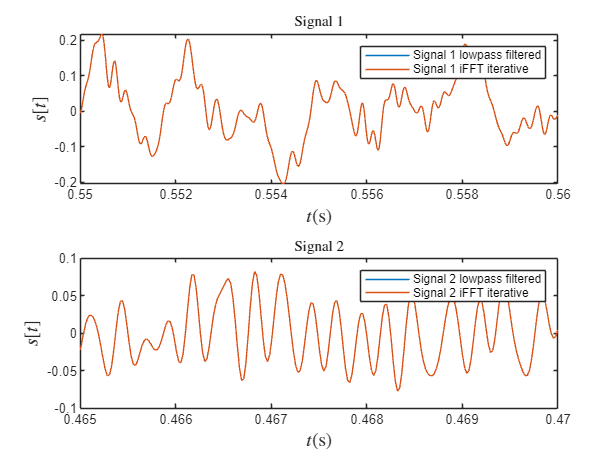

figure()
tiledlayout(2,1);
nexttile
plot(t,h1)
hold on
plot(t,real(iFFT_iterativ_signal_1))
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 lowpass filtered','Signal 1 iFFT iterative')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t,h2)
hold on
plot(t,real(iFFT_iterativ_signal_2))
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 lowpass filtered','Signal 2 iFFT iterative')
xlim([0.465 0.47])%xlim([0 max(t)])

disp(['Comparison lowpassfiltered signal 1 and iFFT iterative signal 1 // Difference = ' num2str(sum(h1-real(iFFT_iterativ_signal_1)))])

Comparison lowpassfiltered signal 1 and iFFT iterative signal 1 // Difference = -2.6252e-15


disp(['Comparison lowpassfiltered signal 2 and iFFT iterative signal 2 // Difference = ' num2str(sum(h2-real(iFFT_iterativ_signal_2)))])

Comparison lowpassfiltered signal 2 and iFFT iterative signal 2 // Difference = -3.2495e-15
